syms w t

L1 = 40.025/100; %m
L2 = 18.28/100; %m

A = -0.027;
phi = pi/2;

r = A*(3+cos((3*w*t)+phi));

x = r*cos(w*t) + 0.2;
y = r*sin(w*t) + 0.4;

v_x = diff(x,t);
v_y = diff(y,t);

v = sqrt(v_x^2+v_y^2);

a_x = diff(v_x,t);
a_y = diff(v_y,t);

theta_2 = -acos((x^2+y^2-L1^2-L2^2)/(2*L1*L2));
omega_2 = diff(theta_2,t);
alpha_2 = diff(omega_2,t);

theta_1 = atan(y/x) - atan(L2*sin(theta_2)/(L1+L2*cos(theta_2)));
omega_1 = diff(theta_1,t);
alpha_1 = diff(omega_1,t);

## Asignación de w y t

theta = 2*pi;
T = 16;
t = linspace(0,T,100);
w = theta/T;
v_min = 0.01; %m/s
v_max = 0.1; %m/s
w = mean([v_min,v_max])/mean(eval(r));

## Posición de HOME

x_home = 0.09; %m
y_home = 0.2072; %m
h_home = sqrt(L1^2-(x_home/2)^2);

theta_2_home = -acos((x_home^2+y_home^2-L1^2-L2^2)/(2*L1*L2));
theta_1_home = atan(y_home/x_home) - atan(L2*sin(theta_2_home)/(L1+L2*cos(theta_2_home)));

## Gráficas

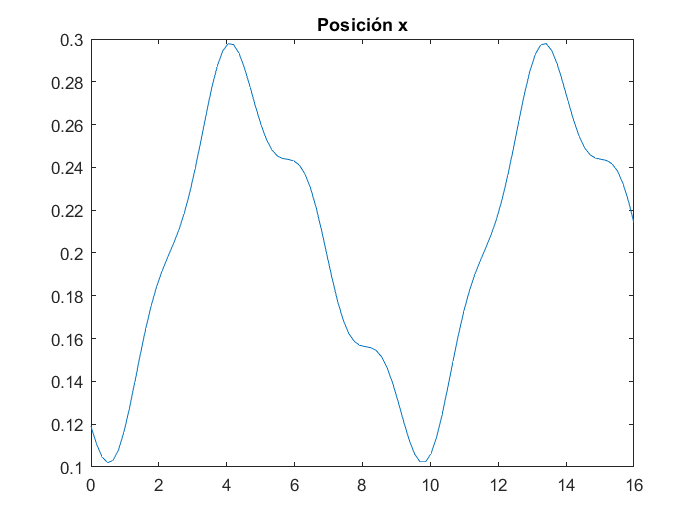

%Posición x
figure()
plot(t,eval(x))
title('Posición x')

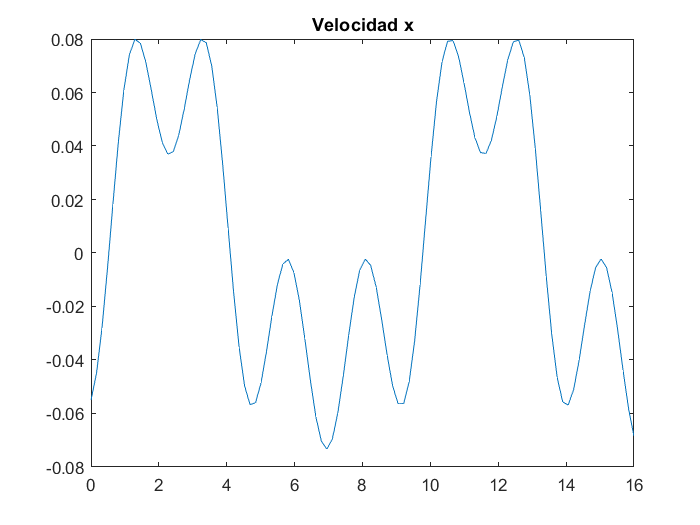

%Velocidad x
figure()
plot(t,eval(v_x))
title('Velocidad x')

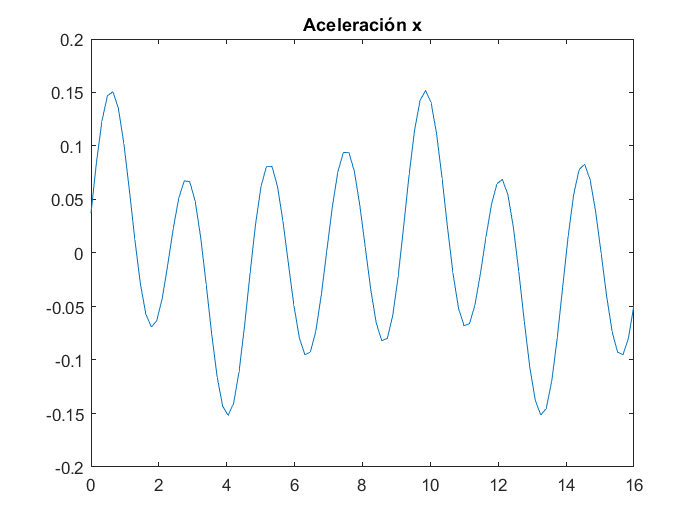

%Aceleración x
figure()
plot(t,eval(a_x))
title('Aceleración x')

## En y

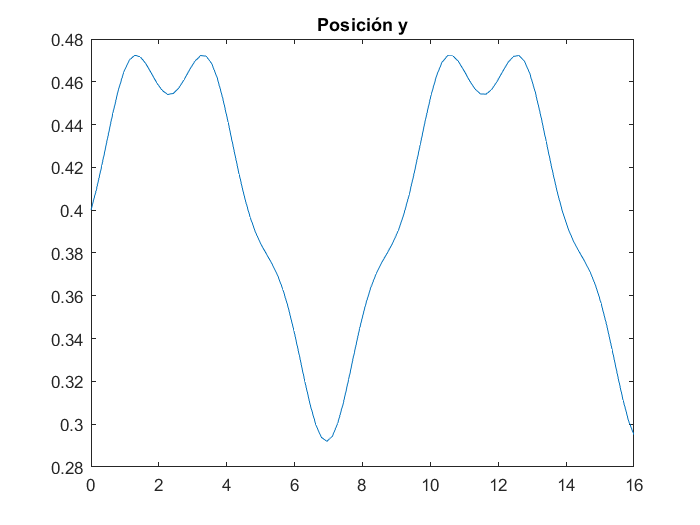

%Posición y
figure()
plot(t,eval(y))
title('Posición y')

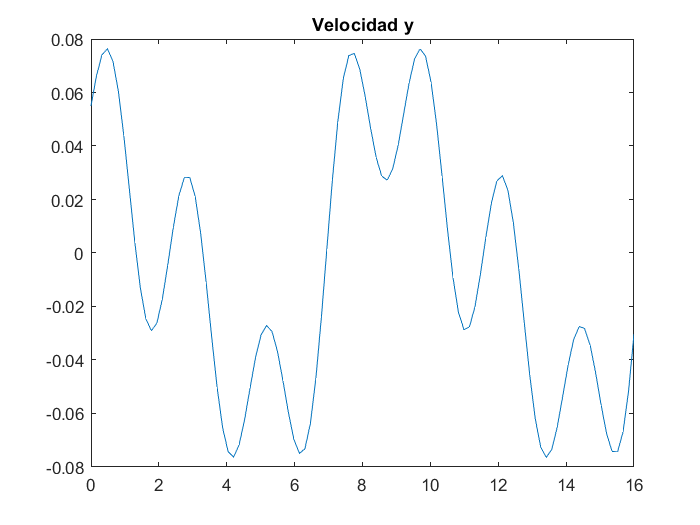

%Velocidad y
figure()
plot(t,eval(v_y))
title('Velocidad y')

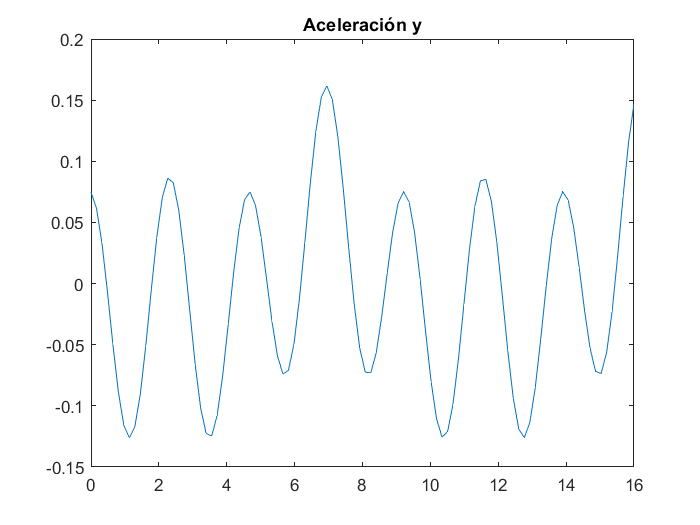

%Aceleración y
figure()
plot(t,eval(a_y))
title('Aceleración y')

## Motor 2

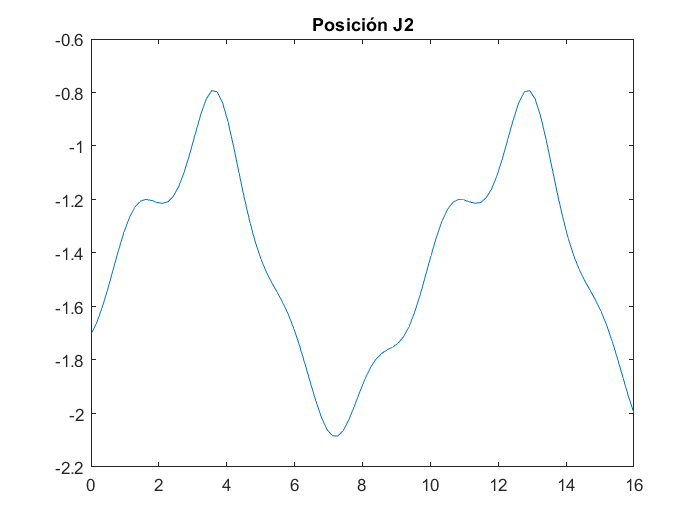

%Posición J2
figure()
plot(t,eval(theta_2))
title('Posición J2')

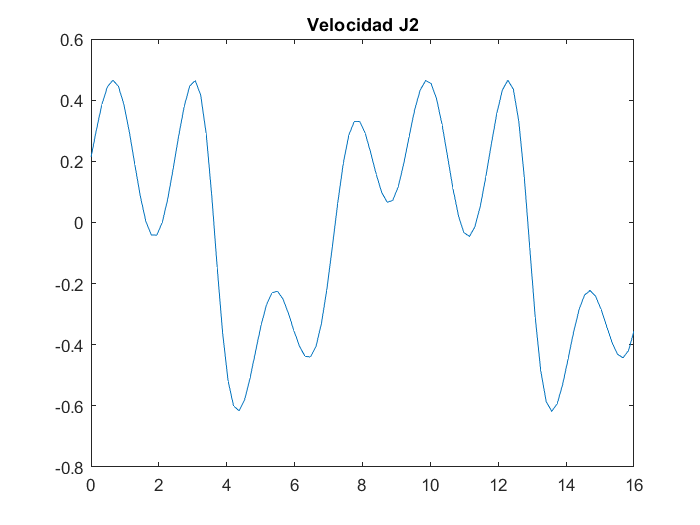

%Velocidad J2
figure()
plot(t,eval(omega_2))
title('Velocidad J2')

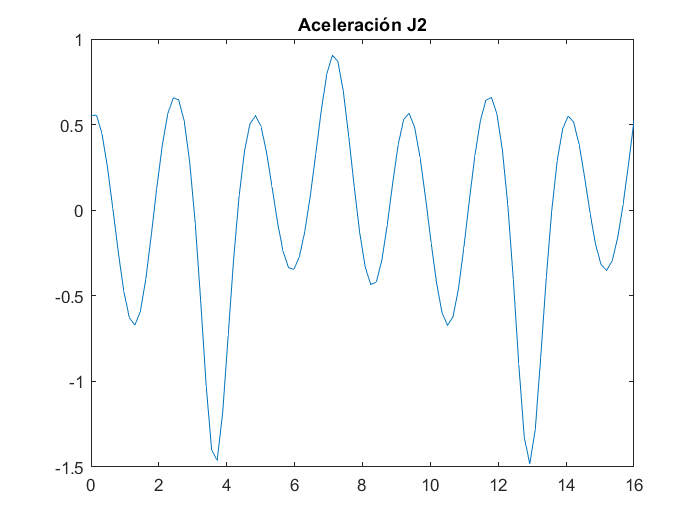

%Aceleración J2
figure()
plot(t,eval(alpha_2))
title('Aceleración J2')

## Motor 1

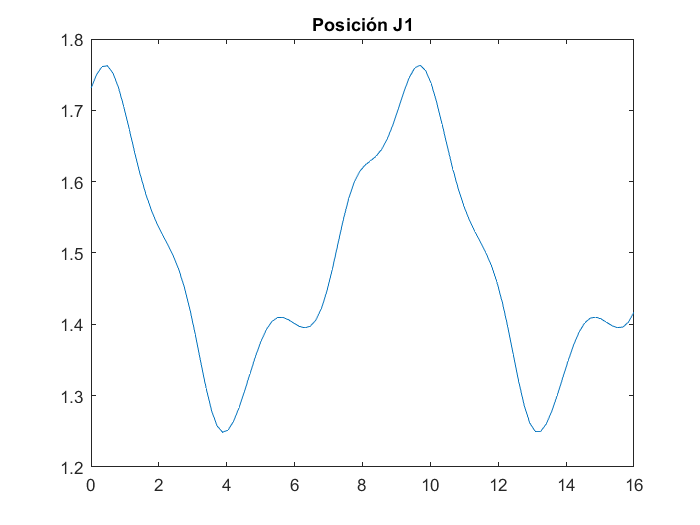

%Posición J1
figure()
plot(t,eval(theta_1))
title('Posición J1')

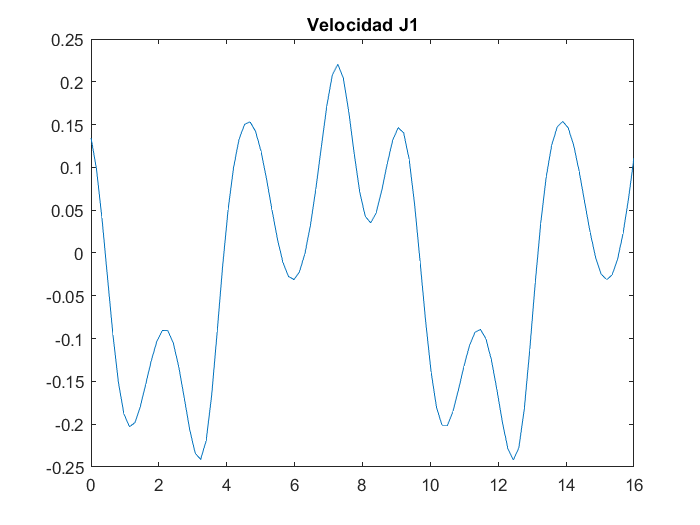

%Velocidad J1
figure()
plot(t,eval(omega_1))
title('Velocidad J1')

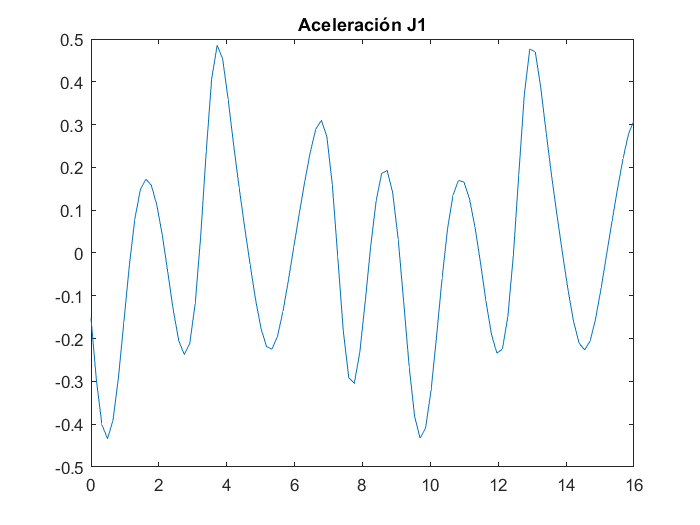

%Aceleración J1
figure()
plot(t,eval(alpha_1))
title('Aceleración J1')

## Posiciones angulares

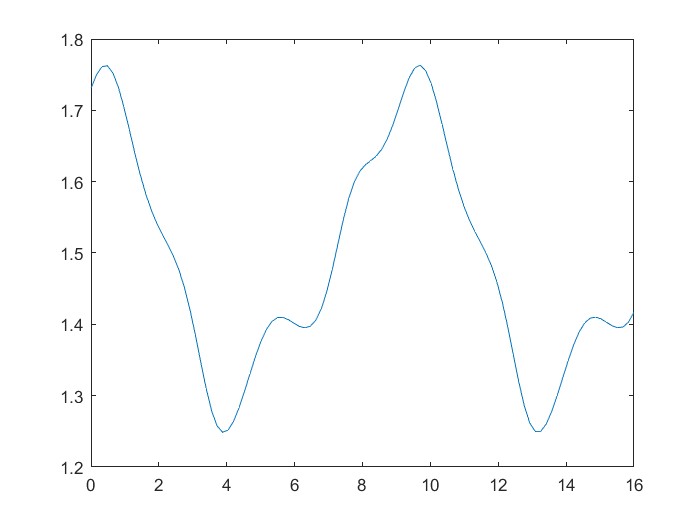

figure()
plot(t,eval(theta_1))

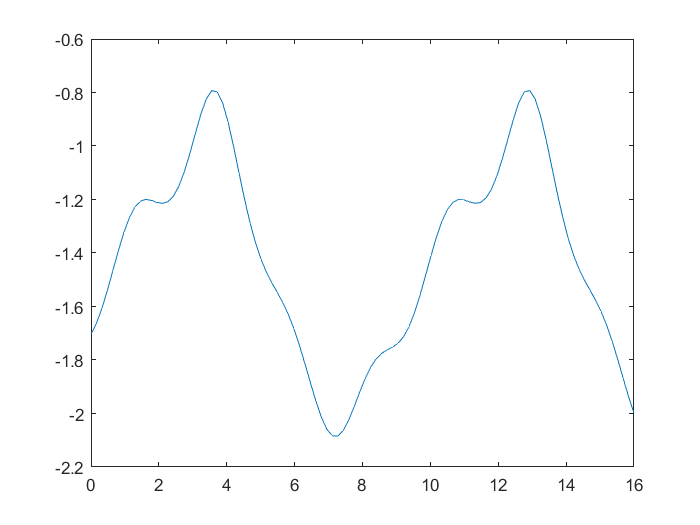


figure()
plot(t,eval(theta_2))

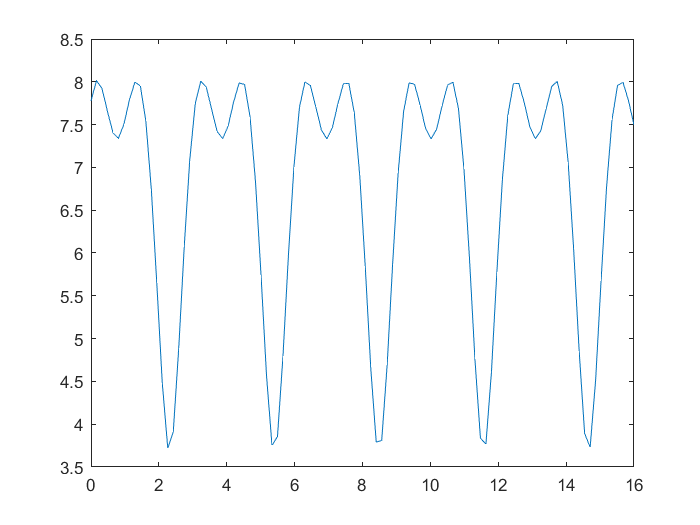


figure()
plot(t,eval(v)*100)